# Tropical Phase Plane Demo

## Autocatalator Phase Plane

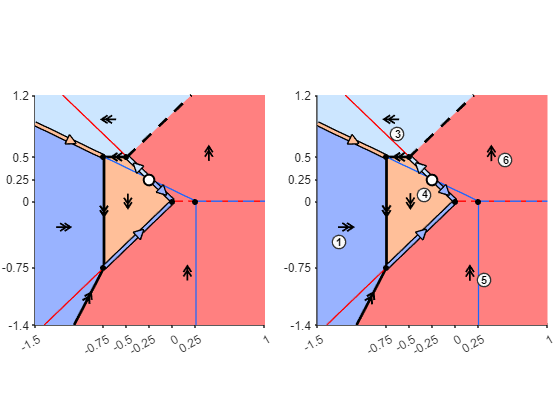

clear
close all
% Parameter
a = 0.25;
% Tropical polynomials: [delta, a, n, m]
F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
% Initialize figure
figure
tiledlayout(1,2,'Padding','none','TileSpacing','compact')
% Phase plane without labels
nexttile
TropicalPhasePlane(F,G)
% Phase plane with labels
nexttile
TropicalPhasePlane(F,G,[],[],true)

## Autocatalator Phase Plane - Bifurcations

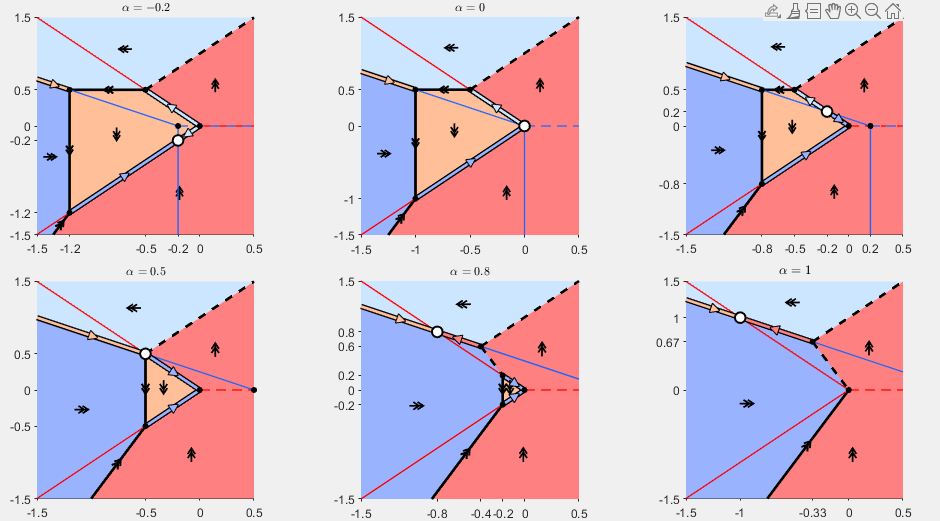

clear
close all
figure("Visible","on","Units","normalized","OuterPosition",[0.1 0.1 .7 .8]);
A = [-0.2 0 0.2 0.5 0.8 1];
ulim = [-1.5 0.5];
vlim = [-1.5 1.5];
tiledlayout(2,3,"Padding","tight","TileSpacing","compact");
for a = A
    F = [1 a-1 -1 0;-1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile
    TropicalPhasePlane(F,G,ulim,vlim)
    title("$\alpha = " + a + "$",'Interpreter',"latex")
end

## Labelled Subdivision

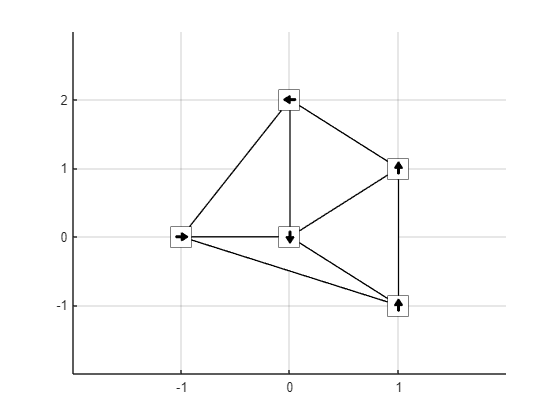

clear
close all
a = 0;
F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
figure
LabelledSubdivision(F,G)

## Lifted Point Configuration

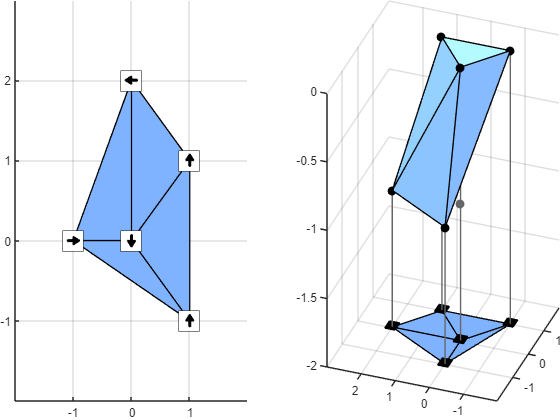

clear
close all
figure
a = 0;
F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
tiledlayout(1,2,"Padding","tight")
nexttile
LabelledSubdivision(F,G,'FaceColor',[0.5 0.7 1])
nexttile
LiftedPointConfiguration(F,G,'FaceColor',[0.5 0.7 1])

## Labelled Subdivision - Bifurcations

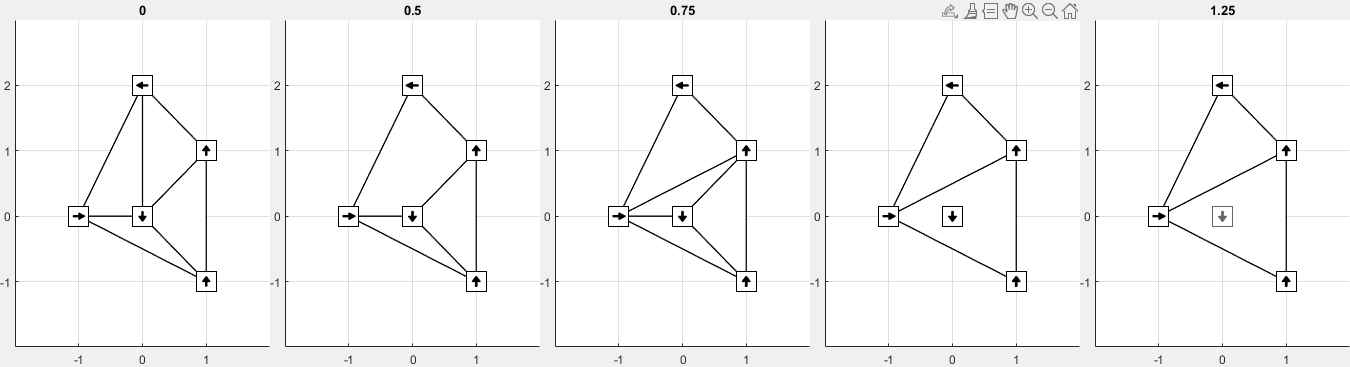

clear
close all
A = [0 0.5 0.75 1 1.25];
figure("Visible","on","Units","normalized","OuterPosition",[0 0.2 1 .6]);
tiledlayout(1,5,'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile
    LabelledSubdivision(F,G)
    title(a)
end

## Lifted Point Configuration - Bifurcations

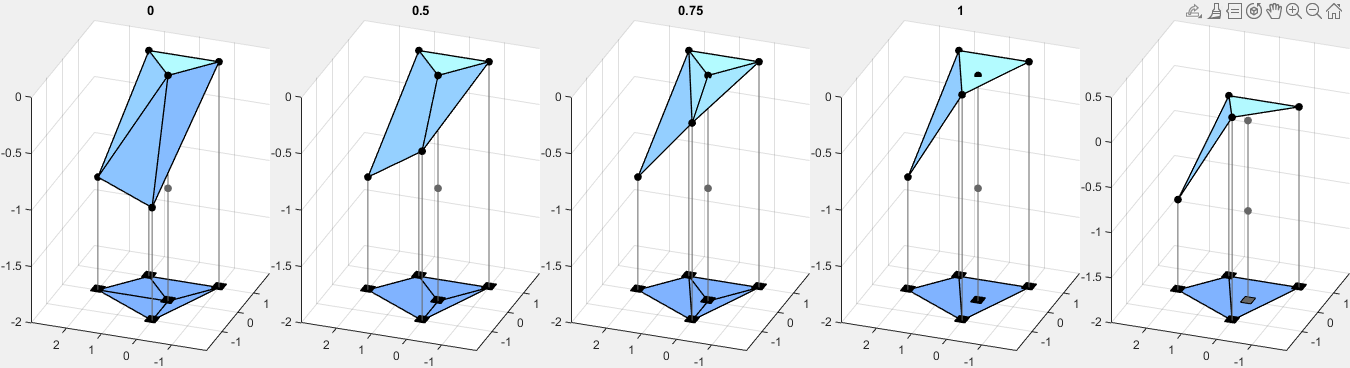

clear
close all
A = [0 0.5 0.75 1 1.25];
figure("Visible","on","Units","normalized","OuterPosition",[0 0.1 1 .6]);
tiledlayout(1,5,'TileSpacing','tight','Padding','tight');
for a = A
    F = [1 a-1 -1 0; -1 -1 0 0; -1 -1 0 2];
    G = [-1 0 0 0; 1 0 1 -1; 1 0 1 1];
    nexttile
    LiftedPointConfiguration(F,G)
    title(a)
end